# 粒子群算法 PSO

## 绘制函数的图形

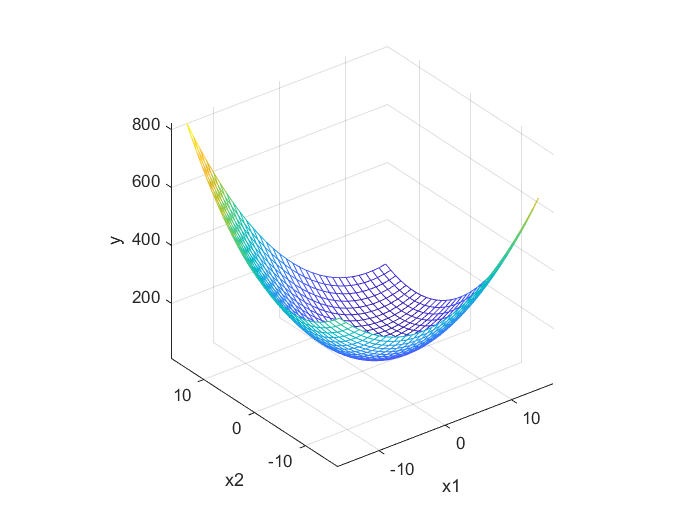

x1 = -15:1:15;
x2 = -15:1:15;
[x1,x2] = meshgrid(x1,x2);
y = x1.^2 + x2.^2 - x1.*x2 - 10*x1 - 4*x2 + 60;
mesh(x1,x2,y)
xlabel('x1');  ylabel('x2');  zlabel('y');  % 加上坐标轴的标签
axis vis3d % 冻结屏幕高宽比，使得一个三维对象的旋转不会改变坐标轴的刻度显示
hold on  % 不关闭图形，继续在上面画图

## 粒子群算法中的预设参数

n = 30; % 粒子数量
narvs = 2; % 变量个数
c1 = 2;  % 每个粒子的个体学习因子，也称为个体加速常数
c2 = 2;  % 每个粒子的社会学习因子，也称为社会加速常数
w = 0.9;  % 惯性权重
K = 100;  % 迭代的次数

vmax = [6 6]; % 粒子的最大速度
x_lb = [-15 -15]; % x的下界
x_ub = [15 15]; % x的上界

## 初始化粒子的位置和速度

x = zeros(n,narvs);
for i = 1: narvs
    x(:,i) = x_lb(i) + (x_ub(i)-x_lb(i))*rand(n,1);    % 随机初始化粒子所在的位置在定义域内
end
v = -vmax + 2*vmax .* rand(n,narvs);  % 随机初始化粒子的速度（这里我们设置为[-vmax,vmax]）
%  注意：这种写法只支持2017及之后的Matlab，老版本的同学请自己使用repmat函数将向量扩充为矩阵后再运算。
% 即：v = -repmat(vmax, n, 1) + 2*repmat(vmax, n, 1) .* rand(n,narvs);  
% 注意：x的初始化也可以用一行写出来：  x = x_lb + (x_ub-x_lb).*rand(n,narvs) ，原理和v的计算一样
% 老版本同学可以用x = repmat(x_lb, n, 1) + repmat((x_ub-x_lb), n, 1).*rand(n,narvs) 



## 计算适应度(注意，因为是最小化问题，所以适应度越小越好)

fit = zeros(n,1);  % 初始化这n个粒子的适应度全为0
for i = 1:n  % 循环整个粒子群，计算每一个粒子的适应度
    fit(i) = Obj_fun2(x(i,:));   % 调用Obj_fun2函数来计算适应度
end 
pbest = x;   % 初始化这n个粒子迄今为止找到的最佳位置（是一个n*narvs的向量）
ind = find(fit == min(fit), 1);  % 找到适应度最小的那个粒子的下标
gbest = x(ind,:);  % 定义所有粒子迄今为止找到的最佳位置（是一个1*narvs的向量）


## 在图上标上这n个粒子的位置用于演示

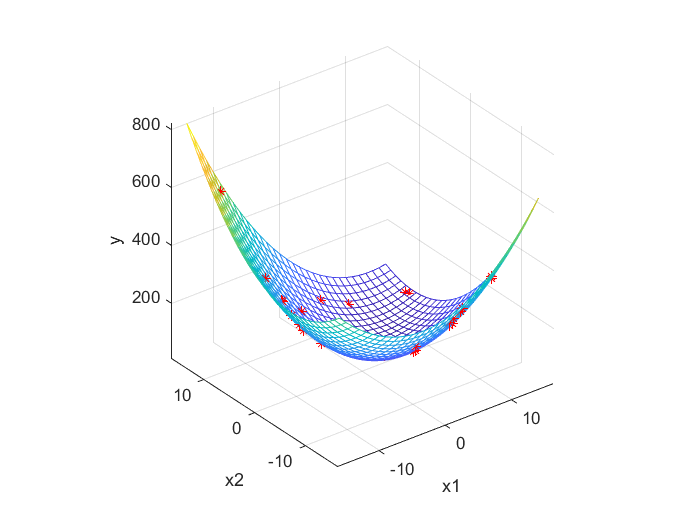

h = scatter3(x(:,1),x(:,2),fit,'*r');  

% scatter3是绘制三维散点图的函数（这里返回h是为了得到图形的句柄，未来我们对其位置进行更新）

## 迭代K次来更新速度与位置

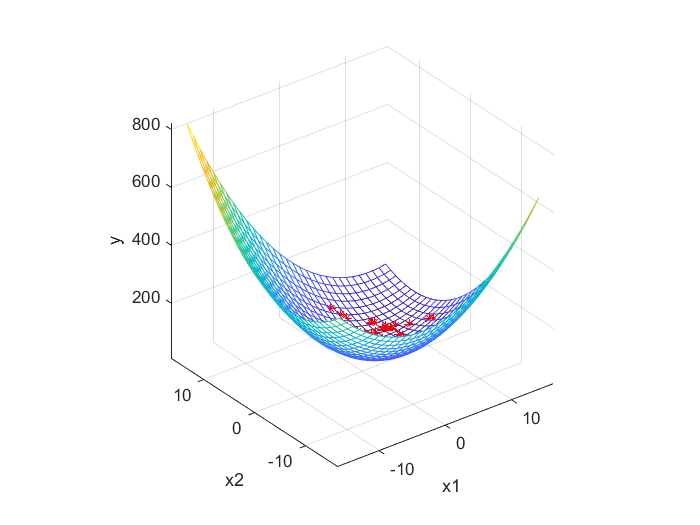

fitnessbest = ones(K,1);  % 初始化每次迭代得到的最佳的适应度
for d = 1:K  % 开始迭代，一共迭代K次
    for i = 1:n   % 依次更新第i个粒子的速度与位置
        v(i,:) = w*v(i,:) + c1*rand(1)*(pbest(i,:) - x(i,:)) + c2*rand(1)*(gbest - x(i,:));  % 更新第i个粒子的速度
        % 如果粒子的速度超过了最大速度限制，就对其进行调整
        for j = 1: narvs
            if v(i,j) < -vmax(j)
                v(i,j) = -vmax(j);
            elseif v(i,j) > vmax(j)
                v(i,j) = vmax(j);
            end
        end
        x(i,:) = x(i,:) + v(i,:); % 更新第i个粒子的位置
        % 如果粒子的位置超出了定义域，就对其进行调整
        for j = 1: narvs
            if x(i,j) < x_lb(j)
                x(i,j) = x_lb(j);
            elseif x(i,j) > x_ub(j)
                x(i,j) = x_ub(j);
            end
        end
        fit(i) = Obj_fun2(x(i,:));  % 重新计算第i个粒子的适应度
        if fit(i) < Obj_fun2(pbest(i,:))   % 如果第i个粒子的适应度小于这个粒子迄今为止找到的最佳位置对应的适应度
           pbest(i,:) = x(i,:);   % 那就更新第i个粒子迄今为止找到的最佳位置
        end
        if  fit(i) < Obj_fun2(gbest)  % 如果第i个粒子的适应度小于所有的粒子迄今为止找到的最佳位置对应的适应度
            gbest = pbest(i,:);   % 那就更新所有粒子迄今为止找到的最佳位置
        end
    end
    fitnessbest(d) = Obj_fun2(gbest);  % 更新第d次迭代得到的最佳的适应度
    pause(0.1)  % 暂停0.1s
    h.XData = x(:,1);  % 更新散点图句柄的x轴的数据（此时粒子的位置在图上发生了变化）
    h.YData = x(:,2);   % 更新散点图句柄的y轴的数据（此时粒子的位置在图上发生了变化）
    h.ZData = fit;  % 更新散点图句柄的z轴的数据（此时粒子的位置在图上发生了变化）
end

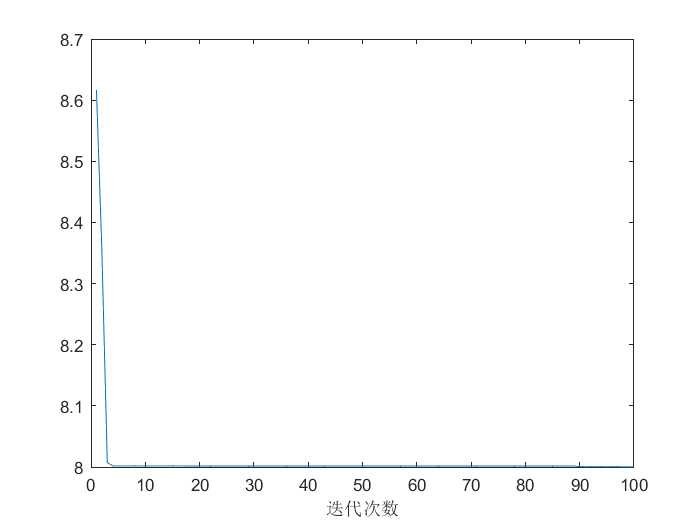


figure(2) 
plot(fitnessbest)  % 绘制出每次迭代最佳适应度的变化图
xlabel('迭代次数');

disp('最佳的位置是：'); disp(gbest)

最佳的位置是：
    7.9876    5.9919



disp('此时最优值是：'); disp(Obj_fun2(gbest))

此时最优值是：
    8.0001



## 适应度函数

function y = Obj_fun2(x)  
% y = x1^2+x2^2-x1*x2-10*x1-4*x2+60
% x是一个向量哦！
    y = x(1)^2 + x(2)^2 - x(1)*x(2) - 10*x(1) - 4*x(2) + 60; % 千万别写成了x1
end